# Robotics 2 - Final Exam - June 17 2019

## Exercise 1

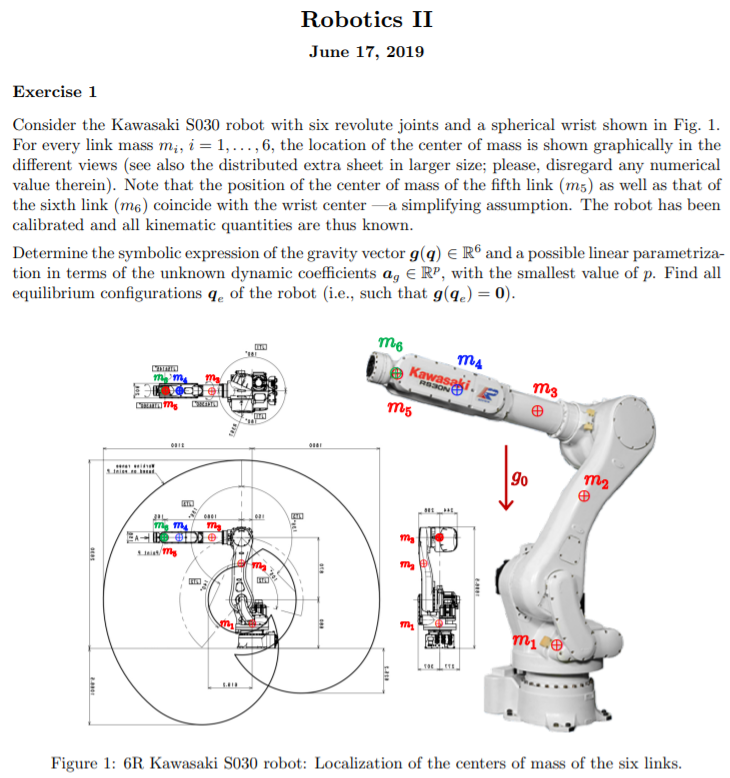

% clear;clc; close all
% sigma = [0;0;0;0;0;0] % 0: Revolute, 1: Prismatic
% n = length(sigma); %Number of joints
% 
% q = sym('q', [n 1],'real');
% qd = sym('qd',[n 1],'real');
% qdd = sym('qdd',[n 1],'real');
% d = sym('d', [n 1],'real');
% a = sym('a', [n 1],'real');
% l = sym('l',[n 1],'real');
% d = sym('d',[n 1],'real');
% m = sym('m',[n 1],'real');
% I = sym('I',[n 1],'real');
% syms g0
% g = [0,0,-g0].' 
% syms r a
% 
% % close all
% % % Lengths just to test
% d1_=10;
% d2_=10;
% a2_=10;
% l_=ones(n,1)
% a_=ones(n,1)
% % % De Luca's approach
%  links = [
%     Revolute('a',0, 'alpha', pi/2 ,'d', l_(1));
%     Revolute('a', l_(2), 'alpha',0,'d', 0 );
%     Revolute('a', 0*l_(3), 'alpha', pi/2 ,'d',0*l_(3));
%     Revolute('a', 0, 'alpha', pi/2 ,'d',l_(4)*3);
%     Revolute('a', l_(5)*0, 'alpha', -pi/2 ,'d',l_(5)*0);
%     Revolute('a', l_(6)*0, 'alpha', 0 ,'d', l_(6));
% 
% %     Prismatic('qlim', [0 len1],'alpha',pi/2,'theta',pi);
% %     Revolute('a', len1, 'alpha', 0 ,'d', 0);
%     ];
% % 
%  c600 = SerialLink(links);
%   c600.teach([0 pi/2,pi/2*0,0,pi/2*0,0],'view','x');
% %  c600.teach([0 pi/2,0,0],'view','x');
% %  c600.teach([0 pi/2,0,0*pi/2,0,0],'view','x');
% 

% dhTable = [pi/2    0    l(1) q(1);
%            0    l(2)    0  q(2);
%            pi/2    0    0  q(3);
%            pi/2    0    l(4)  q(4);
%            -pi/2    0    0  q(5);
%            0    0    l(6)  q(6);
%            ]
%             
% % % alpha,a, d, theta
% % dhTable = [pi/2    0    0  q(1)-pi/2;
% %            0    l(2)    0  q(2);
% %            pi/2    0    0  q(3);
% %            pi/2    0    l(4)  q(4);
% %            -pi/2    0    0  q(5);
% %            0    0    0  q(6);
% %            ]
%        
%  

% %  [g_q,PE,U] = getGravityWithJacobian(dhTable,q,l,m,d,g,0)
% % for i = 1:n
% %     U{i}
% % end

% % [Gsubs, dynamicParamsReturn, a] = getDynamicParameters(g_q,q,[])

## my aproach

% % This part is isolated from previous sectionclear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0,0,0,0,0];
% % sigma = [0,0,0];
% R2Robot=['rrrrrr';'';[1,1,1,1,1,1]]    
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% q_d= sym('q_d', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,0,-g0]';
% 
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=2%with DH table
% z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% z.opt_expr={[dc(5),dc(6)],[0,0]};
% % z.rcdefined=true;

% 
%    
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);

% M

Viscouz terms

% % F_v=sym('F_v',[n,1],'real').*eye(n)

## gravity computation

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% U{:}

% g_q

## get dinamyc paramters

% % [Msubs, dynamicParameters, aM] = getDynamicParameters(M,q,[])
% [Gsubs, dynamicParametersG, aG] = getDynamicParameters3(g_q,q,[g0],2)
% % [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)

% simplify(collect(Gsubs,[g0]))

% % % [C,cac,Csubs] = getCs(Msubs,q',qd';)
% % u =simplify( M*q_ddot + cac+g_q+F_v*q_dot)
% % [usubs, dynamicParametersu, au] = getDynamicParameters(u,q,[])
% % 
% % Msubs = All(:,1:n)
% % gSubs = diag(All(:,n+1:2*n))
% % FSubs = All(:,2*n+1:end)

% % u_subs = Msubs*q_ddot + gSubs +FSubs*q_dot

## Linearization

% % Y=sym('Y','real')
% Y_=getLinearParametrization(Gsubs,aG)

% simplify(Y_)


## Exercise 2

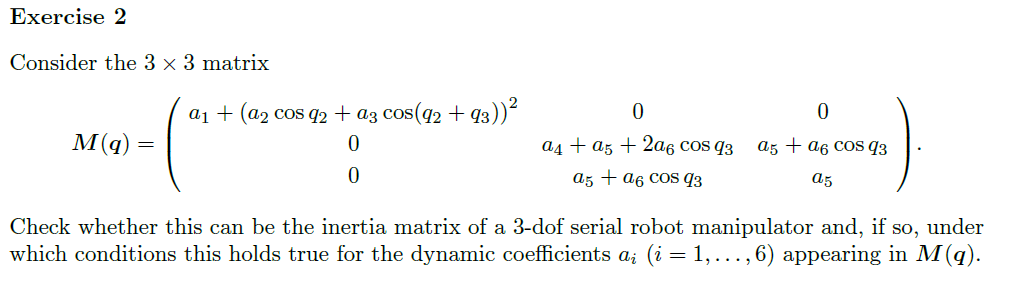

% clear;clc; close all
% syms a1 a2 a3 a4 a5 a6 q1 q2 q3 
% n=3;
% q = sym('q', [n 1],'real');
% qd = sym('qd',[n 1],'real');
% qdd = sym('qdd',[n 1],'real');
% sq=sym('s', [n 1],'real');
% cq=sym('c', [n 1],'real');
% sinq=sin(q);
% cosq=cos(q);
% 
% M2 = [a1+(a2*cos(q2)+a3*cos(q(2)+q(3)))^2 , 0, 0;
%     0, a4+a5+2*a6*cos(q3), a5+a6*cos(q3) ;
%     0, a5+a6*cos(q3) ,  a5]

% % M2subs = subs(M2,sinq,sq)
% % M2subs = subs(M2,cosq,cq)
% sincos_ = getShortNotation_SinCosV2(n);
%     % % Jl_ = toShortNotation(Jl,sincos_)
% M2subs = toShortNotation((M2),sincos_)
% det(M2subs)
% simplify(det(M2))

% simplify(det(M2(1:2,1:2)))

% simplify(det(M2(2:end,2:end)))

% eig(M2)

## Exercise 4

% This part is isolated from previous section
clear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [0,0];
n = length(sigma);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
% 
dc = sym('dc_', [n 1],'real');
% k = sym('k', [n 1],'real');
l = sym('l_', [n 1],'real');
m = sym('m_', [n 1],'real');
% m_p = sym('m_p','real');
% m(2)=m(2)+m_p
I = sym('I_', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,0,-g0]';

s

R2Robot=['rr';'xx';[1,1]]    

R2Robot = 3×2 char array
    'rr'
    'xx'
    ''


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
                 ismoto

% z.dhTable=[]
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
z.opt_expr={[l(1)+q(2)],[q(2)]};
% z.rcdefined=true;
z.joint_on=false;

## torque regulation catesian

z_regulation_torque=Join_Torque_Control_Law_Regulation(z)

$$tau\_def1\_ = c_{q}+M_{q}\,\ddot{q}$$

$$e = p_{d}-p$$

$$e\_ = p_{d}-p$$

$$tau\_def2 = J\,\left(K_{P}\,e-K_{D}\,\dot{p}\right)$$

$$p\_ddot\_def1 = J\,\ddot{q}+\dot{J}\,\dot{q}$$

$$p\_ddot\_def2 = K_{P}\,e-K_{D}\,\dot{p}$$

$$q\_ddot = -\frac{K_{D}\,\dot{p}-K_{P}\,e+\dot{J}\,\dot{q}}{J}$$

$$tau = c_{q}-\frac{M_{q}\,\left(K_{D}\,\dot{p}-K_{P}\,e+\dot{J}\,\dot{q}\right)}{J}$$

z_regulation_torque = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {l_1 + q_2  q_2}
                collides: []
                joint_on: 0
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_refe

## using Cartesian dynamics control LAw


z_regulation_torque_dynamics=cartesian_dynamics_Control_Law_Regulation(z)

$$F\_def1\_ = c_{p}+M_{p}\,\ddot{p}$$

z = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {l_1 + q_2  q_2}
                collides: []
                joint_on: 0
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
         

$$e = p_{d}-p$$

$$e\_ = p_{d}-p$$

$$p\_ddot\_def1 = K_{P}\,e-K_{D}\,\dot{p}$$

$$tau = J^{T}\,\left(c_{p}+M_{p}\,\ddot{p}\right)$$

z_regulation_torque_dynamics = struct with fields:
                  sigmaD: [3×2 char]
                       l: [2×1 sym]
                      l_: []
                       q: [2×1 sym]
                   q_dot: [2×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [2×1 sym]
                       m: [2×1 sym]
                       I: [2×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: t
                      rc: []
            movingframes: 0
                       n: 2
                  angle_: [0    0]
               rcdefined: 1
                opt_expr: {l_1 + q_2  q_2}
                collides: []
                joint_on: 0
                  xyonly: 0
    prismatic_CoM_method: [1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      glob

## dynamic model computation neccessary for the control law

% 
%    
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);
% Trans.Jacobian_PTotal
% Trans.Jacobian_dot_PTotal
% [C,cac,Csubs,S] = getCs(M,q,q_dot);
% cac

Viscouz terms

% % F_v=sym('F_v',[n,1],'real').*eye(n)

% % isMotor=false
% % [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% % U{:}

## get dinamyc paramters

% [Msubs, dynamicParameters, aM] = getDynamicParameters(M,q,[])
% [cacsubs, dynamicParameters, acac] = getDynamicParameters(cac,q,[q_dot]',2)
% % [Gsubs, dynamicParametersG, aG] = getDynamicParameters(g_q,q,[g0],2)
% % [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)

% % u =simplify( M*q_ddot + cac+g_q+F_v*q_dot)
% % [usubs, dynamicParametersu, au] = getDynamicParameters(u,q,[])
% % 
% % Msubs = All(:,1:n)
% % gSubs = diag(All(:,n+1:2*n))
% % FSubs = All(:,2*n+1:end)

% u_subs = Msubs*q_ddot + gSubs +FSubs*q_dot

## Linearization

% Y=sym('Y','real')
% Y_=getLinearParametrization(u_subs,a)

## Adpative control law

%z_u.vartoderivate="q";
% z_u.Y=Y;
% z_u.Y_=Y_;
% z_u.q=q;
% z_u.q_d=q_d%q desired
% t=sym('t','real');
% q_dots=derivate_D(q_d,n,t,'q_d');
% z_u.q_d_dot =q_dots.dot;
% z_u.q_d_ddot=q_dots.ddot;
% z_u.a=a;
% z_u.n=n;
% z_u.q_dot=q_dot;
% z_u.q_ddot=q_ddot;
% 
% u_control=Adpatative_Control_Law(z_u)
% u_control.Y_r_
% u_control.u
% u_control.u_
% u_control.a_hat_dot
% u_control.a_hat_dot_
% u_control.mq_r_dot %I'm not sure about this
% u_control.q_r_dot_
% 
% 

% % clear;clc
% % sigma = [0;0] % 0: Revolute, 1: Prismatic
% % n = length(sigma); %Number of joints
% % 
% % q = sym('q', [n 1]);
% % d = sym('d', [n 1]);
% % a = sym('a', [n 1]);
% % qd = sym('qd',[n 1])
% % l = sym('l',[n 1])
% % d = sym('d',[n 1])
% % m = sym('m',[n 1])
% % I = sym('I',[n 1])
% % syms g0
% % g = [0 -g0 0].'
% % 
% % % alpha,a, d, theta
% % dhTable = [0 l(1) 0 q(1);
% %            0 l(2) 0 q(2)]
% %        

% % [KE,T] = getKEwithJacobian(dhTable,sigma,q,qd,l,m,I,d,0)
% % M= getInertiaMatrixFromKE(KE,qd)

% % [c, S] = getcS(M,q,qd)

% % [g_q,PE,U ] = getGravityWithJacobian(dhTable,q,l,m,d,g,0)

% % [Ttotal, TPartial] = getTransformationMatrix(dhTable,'alpha')

% % [Jp,Jo] = getJacobian(dhTable,sigma,'alpha')

% % var_ind = 't';
% % var_dep = 'q';
% % var_set =[]
% % syms(var_ind)
% % for i=1:n
% %    var_dep_str = strcat(var_dep,num2str(i),'(',var_ind,')');
% %    syms(var_dep_str);
% %    var_set = [var_set str2sym(var_dep_str)]; % appends the variable to the set
% % end
% % syms t
% % qt = var_set.'
% % qdt = diff(qt,t)

% % Jsubs = subs(J,q,qt)

% % Jdsubs = diff(Jsubs,t)

% % Jd = subs(Jdsubs,diff(qt),qd)
% % Jd = subs(Jd,qt,q)

% % qddt = diff(diff(qt,t))
% % 
% % % back to normal coordinates.
% % Jdd1 = subs(Jdd,diff(diff(qt)),qdd);
% % Jdd1 = subs(Jdd1,diff(qt),qd);
% % Jdd1 = subs(Jdd1,qt,q)
% % 

% % Jinv = inv(Jp(1:2,:))

% % p = Ttotal(1:2,4)

% % pt = subs(p,q,qt)

% % pdt = diff(pt)
% % pddt = diff(pdt)

% % pd = subs(pdt,diff(qt),qd)
% % pd = subs(pd,qt,q)

% % pdd = subs(pddt,diff(diff(qt)),qdd);
% % pdd = subs(pdd,diff(qt),qd);
% % pdd = subs(pdd,qt,q)

% % syms pdx pdy
% % pdesired = [pdx;pdy]

% % pdd + [20,0;0,10]*pd + [100,0;0,50]*(pdesired-p)